%%initialize environment
defaultDir = 'M:\Bergles Lab Data\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 2 - SGNs');


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_PhysTemp\180808_Cell1\18808011_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1455.3 s ~ 24 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 555 MB


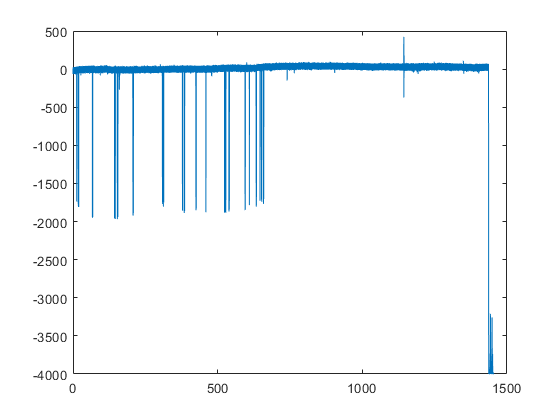

%load files
list = loadFileList('.\Data\WT_MRS_SGN_WC_PhysTemp\*\*_gfv.abf');

for i = 1:size(list,1)
    [d,time] = loadPclampData(list{i});
    figure;
    plot(time,d);
end

## analysis

%Control + MRS _ PT
miniburst_thr = 20; %time must be below XX ms to be considered a miniburst
burst_thr = 1000; %time must be below XX ms to be condidered a burst
           
WT_SGN_paths = loadFileList('.\Data\WT_MRS_SGN_WC_PhysTemp\*\*_gfv.abf');
MRS_times = [0,600,780,1380;];

for i = 1:size(WT_SGN_paths,1)
    [b_spikes, b_ISIs, b_locs] = SGN_ISI_WC(WT_SGN_paths{i},MRS_times(i,1:2));
    [intervals, burst_locs, num_bursts, spikesPerBurst,burst_dur] = SGNbursts(b_ISIs, miniburst_thr, burst_thr, b_locs);
    bursts = struct('intervals',intervals, 'burst_locs',burst_locs,'num_bursts', num_bursts,'spikesPerBurst', spikesPerBurst,'burst_dur', burst_dur);
    [fp, name, ext] = fileparts(WT_SGN_paths{i})
    save([fp '\' name '_spikes.mat'], 'b_spikes', 'b_ISIs', 'b_locs','bursts','-mat');
    
    [b_spikes, b_ISIs, b_locs] = SGN_ISI_WC(WT_SGN_paths{i},MRS_times(i,3:4));
    [intervals, burst_locs, num_bursts, spikesPerBurst,burst_dur] = SGNbursts(b_ISIs, miniburst_thr, burst_thr, b_locs);
    bursts = struct('intervals',intervals, 'burst_locs',burst_locs,'num_bursts', num_bursts,'spikesPerBurst', spikesPerBurst,'burst_dur', burst_dur);
    [fp, name, ext] = fileparts(WT_SGN_paths{i})
    save([fp '\' name '_spikes_MRS.mat'], 'b_spikes', 'b_ISIs', 'b_locs','bursts','-mat');
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_PhysTemp\180808_Cell1\18808011_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1455.3 s ~ 24 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 555 MB
Baseline Spikes (Freq):189.000000 (0.000315)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_PhysTemp\180808_Cell1'

name = '18808011_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_PhysTemp\180808_Cell1\18808011_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1455.3 s ~ 24 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 555 MB


Baseline Spikes (Freq):0.000000 (0.000000)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_PhysTemp\180808_Cell1'

name = '18808011_gfv'

ext = '.abf'


%Control + MRS _ RT
miniburst_thr = 20; %time must be below XX ms to be considered a miniburst
burst_thr = 1000; %time must be below XX ms to be condidered a burst
           
WT_SGN_paths = loadFileList('.\Data\WT_MRS_SGN_WC_RoomTemp\*\*_gfv.abf');
MRS_times = [0,600,780,1380;];

for i = 1:size(WT_SGN_paths,1)
    [b_spikes, b_ISIs, b_locs] = SGN_ISI_WC(WT_SGN_paths{i},MRS_times(i,1:2));
    [intervals, burst_locs, num_bursts, spikesPerBurst,burst_dur] = SGNbursts(b_ISIs, miniburst_thr, burst_thr, b_locs);
    bursts = struct('intervals',intervals, 'burst_locs',burst_locs,'num_bursts', num_bursts,'spikesPerBurst', spikesPerBurst,'burst_dur', burst_dur);
    [fp, name, ext] = fileparts(WT_SGN_paths{i})
    save([fp '\' name '_spikes.mat'], 'b_spikes', 'b_ISIs', 'b_locs','bursts','-mat');
    
    [b_spikes, b_ISIs, b_locs] = SGN_ISI_WC(WT_SGN_paths{i},MRS_times(i,3:4));
    [intervals, burst_locs, num_bursts, spikesPerBurst,burst_dur] = SGNbursts(b_ISIs, miniburst_thr, burst_thr, b_locs);
    bursts = struct('intervals',intervals, 'burst_locs',burst_locs,'num_bursts', num_bursts,'spikesPerBurst', spikesPerBurst,'burst_dur', burst_dur);
    [fp, name, ext] = fileparts(WT_SGN_paths{i})
    save([fp '\' name '_spikes_MRS.mat'], 'b_spikes', 'b_ISIs', 'b_locs','bursts','-mat');
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_RoomTemp\180808_Cell2\18808021_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 916 MB
Baseline Spikes (Freq):187.000000 (0.000312)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_RoomTemp\180808_Cell2'

name = '18808021_gfv'

ext = '.abf'

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_RoomTemp\180808_Cell2\18808021_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2400.0 s ~ 40 min
sampling interval: 20 µs
memory requirement for complete upload in matlab: 916 MB
Baseline Spikes (Freq):111.000000 (0.000185)


fp = 'M:\Bergles Lab Data\Papers\P2ry1\Figure 2 - SGNs\Data\WT_MRS_SGN_WC_RoomTemp\180808_Cell2'

name = '18808021_gfv'

ext = '.abf'

edges = 10.^(-1:0.1:6);
edges2 = 1.13*10.^(-1:0.1:6);
midpoint = sqrt(edges(1:end-1).*edges(2:end));
test = [edges' edges2' [midpoint'; NaN]];

WT_SGN_data = loadFileList('.\Data\WT_MRS_SGN_WC_RoomTemp\*\*_spikes.mat');
WT_numBursts = []; WT_spikesPerBurst = []; WT_burstDur = []; WT_spikeCounts = []; WT_binCounts = [];
WT_CVISI = [];
for i=1:size(WT_SGN_data)
    load(WT_SGN_data{i});
    h = histcounts(b_ISIs, edges);
    WT_binCounts(i,:) = h;
    WT_numBursts(i,1) = bursts.num_bursts; 
    WT_spikesPerBurst(i,1) = bursts.spikesPerBurst;
    WT_burstDur(i,1) =  bursts.burst_dur;
    WT_spikeCounts(i,1) = b_spikes/600;
    WT_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
end

MRS_SGN_data = loadFileList('.\Data\WT_MRS_SGN_WC_RoomTemp\*\*_spikes_MRS.mat');
MRS_numBursts = []; MRS_spikesPerBurst = []; MRS_burstDur = []; MRS_spikeCounts = []; MRS_binCounts = [];
MRS_CVISIs = [];
for i=1:size(WT_SGN_data)
    load(MRS_SGN_data{i});
    h = histcounts(b_ISIs, edges);
    MRS_binCounts(i,:) = h;
    MRS_numBursts(i,1) = bursts.num_bursts; 
    MRS_spikesPerBurst(i,1) = bursts.spikesPerBurst;
    MRS_burstDur(i,1) =  bursts.burst_dur;
    MRS_spikeCounts(i,1) = b_spikes/600;
    MRS_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
end

 dim = [1 1.5]

dim =     1.0000    1.5000


 [h, p] = compare2P(WT_numBursts/10,MRS_numBursts/10,{'WT', 'MRS'}, 'Bursts per minute', dim);

   NaN



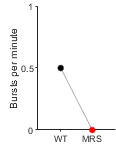

 ylim([0 1]);
 yticks([0:.5:1]);
 figQuality(gcf,gca,dim)
 export_fig('.\EPS Panels\MRS_burstNum.eps',gcf);  

    
[h, p] = compare2P(WT_spikesPerBurst,MRS_spikesPerBurst,{'WT', 'MRS'}, 'Spikes per burst', dim);

   NaN



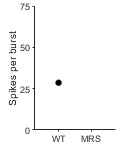

ylim([0 75]);
yticks([0:25:75]);   
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_spikesPerBurst.eps',gcf);

    
[h, p] = compare2P(WT_burstDur/1000,MRS_burstDur/1000,{'WT', 'MRS'}, 'Burst duration (s)', dim);

   NaN



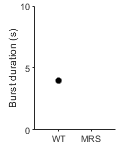

ylim([0 10]);
yticks([0:5:10]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_burstDuration.eps',gcf);


[h, p] = compare2P(WT_CVISI,MRS_CVISI,{'WT', 'MRS'}, 'CVISI', dim);

   NaN



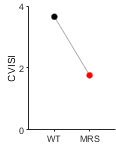

ylim([0 4]);
yticks([0:2:4]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_CVISIs.eps',gcf);

    

[h, p] = compare2P(WT_spikeCounts, MRS_spikeCounts,{'WT', 'MRS'}, 'Spike frequency (Hz)', dim);

   NaN



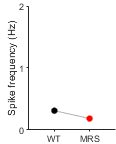

ylim([0 2])
yticks([0:1:2])
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_spikeFreq.eps',gcf);

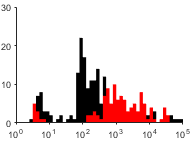


figure; 
histogram('BinCounts', mean(WT_binCounts,1), 'BinEdges', edges,'FaceAlpha',1,'EdgeColor','none', 'FaceColor','k'); hold on;
histogram('BinCounts', mean(MRS_binCounts,1), 'BinEdges', edges,'FaceAlpha',1,'EdgeColor','none','FaceColor','r');
set(gca,'XScale','log');
axis([10^0 10^5 -inf inf]);
errorbar(edges2(1:end-1),mean(WT_binCounts,1),sterr(WT_binCounts,1),'LineStyle', 'none','Color','k','CapSize',0);
errorbar(edges2(1:end-1),mean(MRS_binCounts,1),sterr(MRS_binCounts,1),'LineStyle', 'none','Color','r','CapSize',0);
xticks([10^0,10^1,10^2,10^3,10^4,10^5])
ylim([0 30]);
yticks([0:10:30]);
set(gca,'XminorTick','off')
xticklabels({'10^0','10^1','10^2','10^3','10^4','10^5'})
figQuality(gcf,gca,[2 1.5])
export_fig('.\EPS Panels\MRS_ISIhisto.eps',gcf);


edges = 10.^(-1:0.1:6);
edges2 = 1.13*10.^(-1:0.1:6);
midpoint = sqrt(edges(1:end-1).*edges(2:end));
test = [edges' edges2' [midpoint'; NaN]];

WT_SGN_data = loadFileList('.\Data\WT_MRS_SGN_WC_PhysTemp\*\*_spikes.mat');
WT_numBursts = []; WT_spikesPerBurst = []; WT_burstDur = []; WT_spikeCounts = []; WT_binCounts = [];
WT_CVISI = [];
for i=1:size(WT_SGN_data)
    load(WT_SGN_data{i});
    h = histcounts(b_ISIs, edges);
    WT_binCounts(i,:) = h;
    WT_numBursts(i,1) = bursts.num_bursts; 
    WT_spikesPerBurst(i,1) = bursts.spikesPerBurst;
    WT_burstDur(i,1) =  bursts.burst_dur;
    WT_spikeCounts(i,1) = b_spikes/600;
    WT_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
end

MRS_SGN_data = loadFileList('.\Data\WT_MRS_SGN_WC_PhysTemp\*\*_spikes_MRS.mat');
MRS_numBursts = []; MRS_spikesPerBurst = []; MRS_burstDur = []; MRS_spikeCounts = []; MRS_binCounts = [];
MRS_CVISIs = [];
for i=1:size(WT_SGN_data)
    load(MRS_SGN_data{i});
    h = histcounts(b_ISIs, edges);
    MRS_binCounts(i,:) = h;
    if ~isempty(bursts.num_bursts)
        MRS_numBursts(i,1) = bursts.num_bursts; 
        MRS_spikesPerBurst(i,1) = bursts.spikesPerBurst;
        MRS_burstDur(i,1) =  bursts.burst_dur;
        MRS_spikeCounts(i,1) = b_spikes/600;
        MRS_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
    else
        MRS_numBursts(i,1) = NaN; 
        MRS_spikesPerBurst(i,1) = NaN;
        MRS_burstDur(i,1) =  NaN;
        MRS_spikeCounts(i,1) = b_spikes/600;
        MRS_CVISI(i,1) = std(b_ISIs,[],1)/mean(b_ISIs,1);
    end
end

 dim = [1 1.5]

dim =     1.0000    1.5000


 [h, p] = compare2P(WT_numBursts/10,MRS_numBursts/10,{'WT', 'MRS'}, 'Bursts per minute', dim);

   NaN



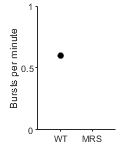

 ylim([0 1]);
 yticks([0:.5:1]);
 figQuality(gcf,gca,dim)
 export_fig('.\EPS Panels\MRS_burstNum.eps',gcf);  

    
[h, p] = compare2P(WT_spikesPerBurst,MRS_spikesPerBurst,{'WT', 'MRS'}, 'Spikes per burst', dim);

   NaN



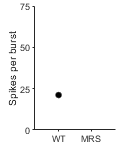

ylim([0 75]);
yticks([0:25:75]);   
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_spikesPerBurst.eps',gcf);

    
[h, p] = compare2P(WT_burstDur/1000,MRS_burstDur/1000,{'WT', 'MRS'}, 'Burst duration (s)', dim);

   NaN



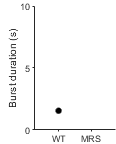

ylim([0 10]);
yticks([0:5:10]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_burstDuration.eps',gcf);


[h, p] = compare2P(WT_CVISI,MRS_CVISI,{'WT', 'MRS'}, 'CVISI', dim);

   NaN



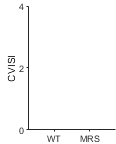

ylim([0 4]);
yticks([0:2:4]);
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_CVISIs.eps',gcf);

    

[h, p] = compare2P(WT_spikeCounts, MRS_spikeCounts,{'WT', 'MRS'}, 'Spike frequency (Hz)', dim);

   NaN



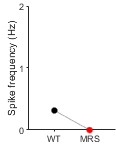

ylim([0 2])
yticks([0:1:2])
figQuality(gcf,gca,dim)
export_fig('.\EPS Panels\MRS_spikeFreq.eps',gcf);

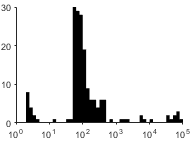


figure; 
histogram('BinCounts', mean(MRS_binCounts,1), 'BinEdges', edges,'FaceAlpha',1,'EdgeColor','none','FaceColor','r'); hold on;
histogram('BinCounts', mean(WT_binCounts,1), 'BinEdges', edges,'FaceAlpha',1,'EdgeColor','none', 'FaceColor','k'); hold on;

set(gca,'XScale','log');
axis([10^0 10^5 -inf inf]);
errorbar(edges2(1:end-1),mean(WT_binCounts,1),sterr(WT_binCounts,1),'LineStyle', 'none','Color','k','CapSize',0);
errorbar(edges2(1:end-1),mean(MRS_binCounts,1),sterr(MRS_binCounts,1),'LineStyle', 'none','Color','r','CapSize',0);
xticks([10^0,10^1,10^2,10^3,10^4,10^5])
ylim([0 30]);
yticks([0:10:30]);
set(gca,'XminorTick','off')
xticklabels({'10^0','10^1','10^2','10^3','10^4','10^5'})
figQuality(gcf,gca,[2 1.5])
export_fig('.\EPS Panels\MRS_ISIhisto.eps',gcf);